# Loading and Viewing Indexed Images of Bear Glacier

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

info1980 = imfinfo("./images/bearGlacier1980.png");
type1980 = info1980.ColorType

type1980 = 'indexed'

info2011 = imfinfo("./images/bearGlacier2011.png")

info2011 = struct with fields:
                  Filename: 'C:\Users\luisa\GitHub\MATLAB_Courses\Image_Processing_with_MATLAB\Working_with_Image_Data\images\bearGlacier2011.png'
               FileModDate: '08-May-2023 15:52:39'
                  FileSize: 356928
                    Format: 'png'
             FormatVersion: []
                     Width: 1502
                    Height: 1121
                  BitDepth: 8
                 ColorType: 'indexed'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: [20×3 double]
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'none'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: []
            Chromaticities: []
                     Gamma: []
               XResolution: []
               YResolution: []
            ResolutionUnit: []
                   XOffset: []
                   YOffset: []
                OffsetUnit: [

type2011 = info2011.ColorType

type2011 = 'indexed'

## Task 1

You can see in the initialization code that the images of Bear Glacier are indexed images.

When you import an indexed image, you need to import the map as well. You can do this by requesting a second output from `imread`.

`[I,map] = imread("filename.png");`

[glacier1980, map1980] = imread("./images/bearGlacier1980.png");

## Task 2

To display an indexed image, provide both the indexed image and the map to `imshow`.

`imshow``(``I``,``map``)`

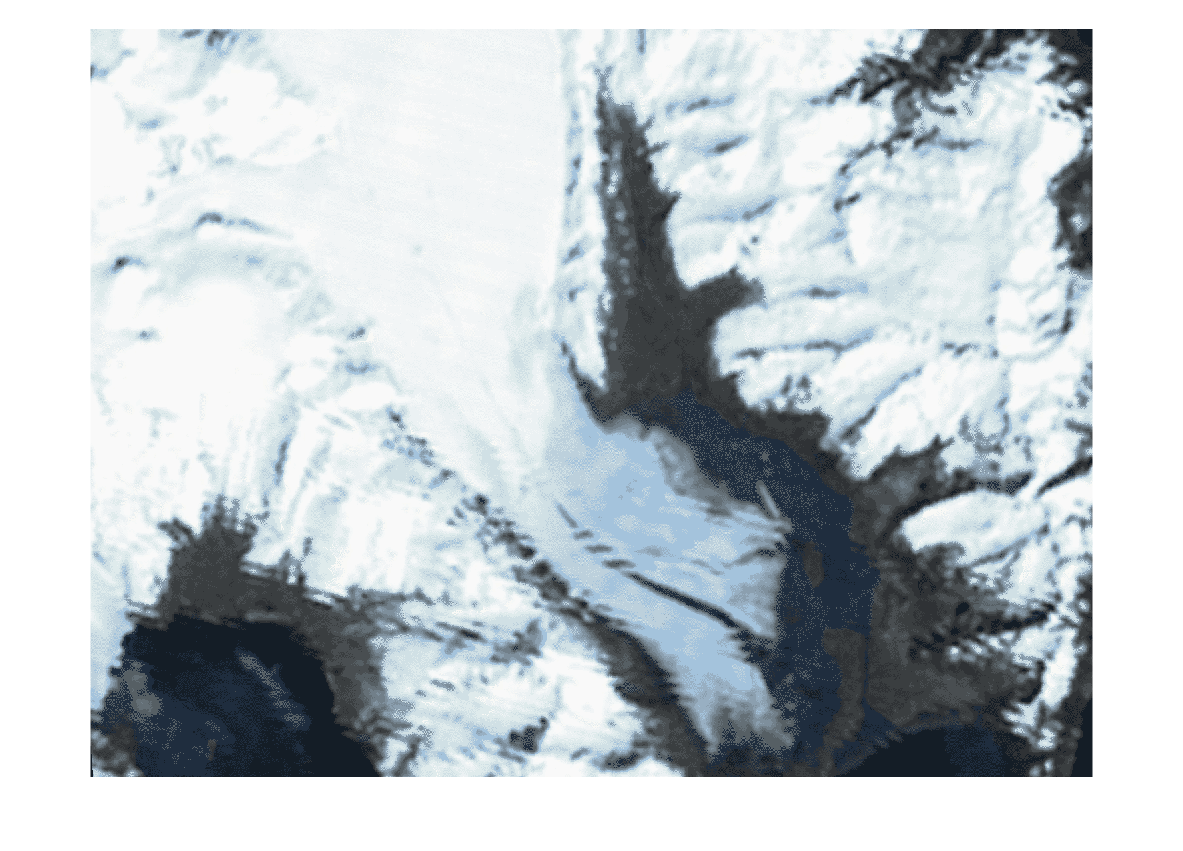

imshow(glacier1980, map1980)

## Task 3

The `title` command also works on images.

`title``(``"Image Title"``)`

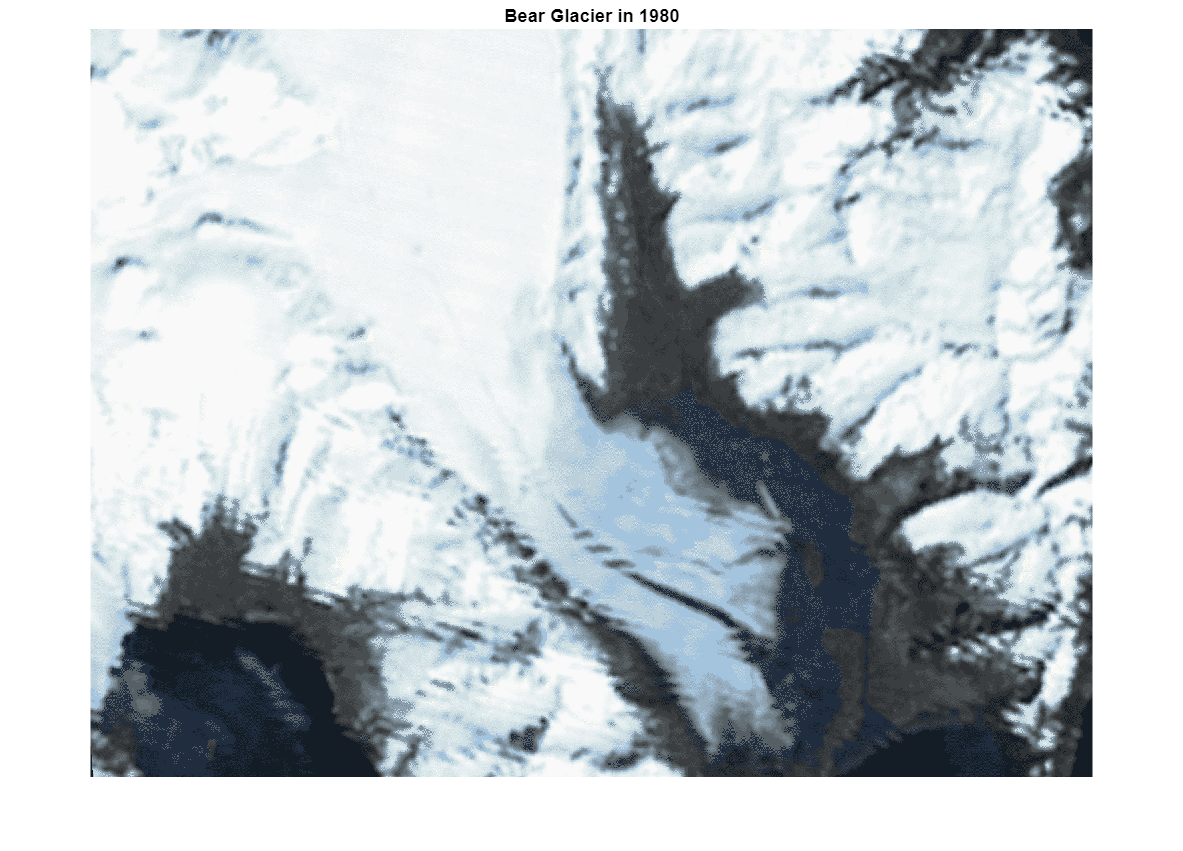

title("Bear Glacier in 1980")

## Task 4

The 2011 image of Bear Glacier is in the file bearGlacier2011.png.

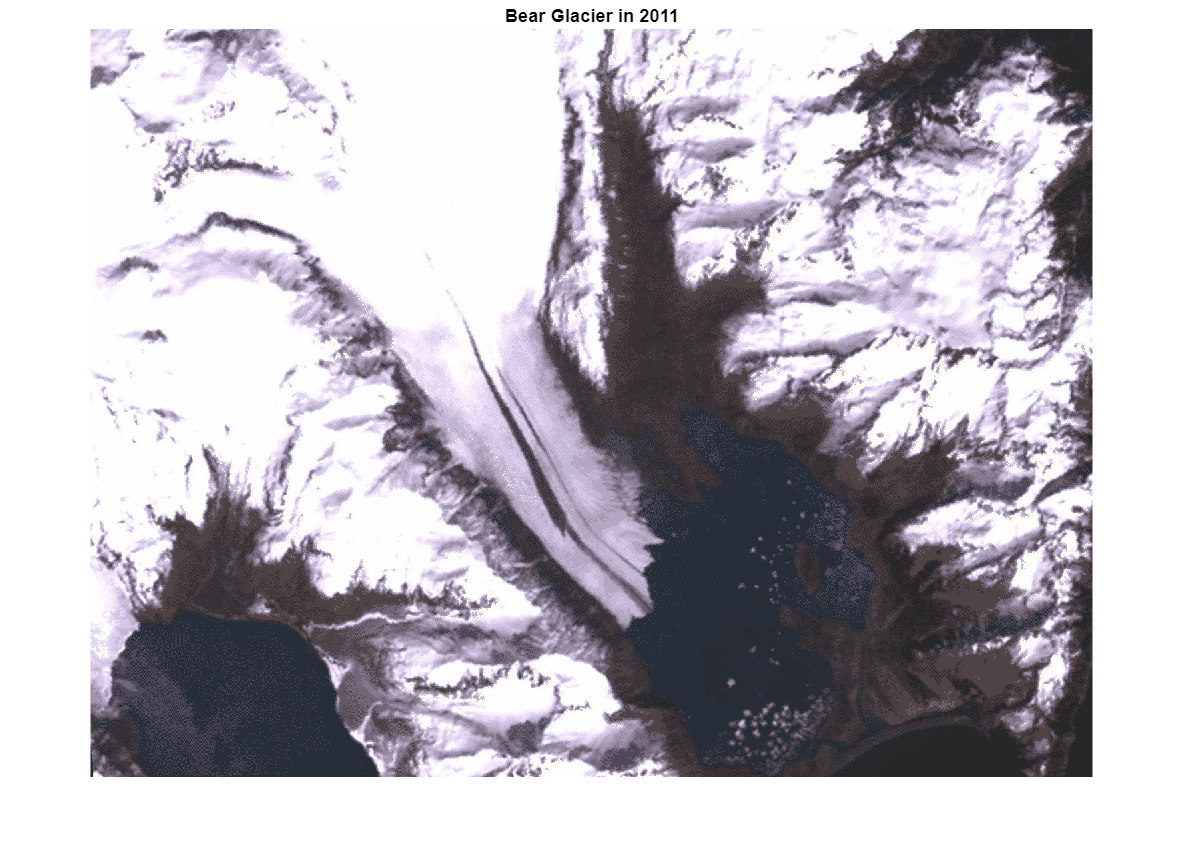

[glacier2011, map2011] = imread("./images/bearGlacier2011.png");
imshow(glacier2011, map2011)
title("Bear Glacier in 2011")

## Task 5

For some image processing tasks, you need grayscale or RGB images. For instance, `imshowpair` requires either grayscale or RGB to display the images as you would expect.

You can convert from an indexed image to a RGB or grayscale image with `ind2rgb` or  `ind2gray`.

`rgb` `=` `ind2rgb``(``I``,``map``)``;`

`gs` `=` `ind2gray``(``I``,``map``)``;`

gs1980 = ind2gray(glacier1980, map1980);
gs2011 = ind2gray(glacier2011, map2011);

## Task 6

You can use the `"montage"` method of `imshowpair` to display images side-by-side.

`imshowpair``(``I1``,``I2``,``"montage"``)`

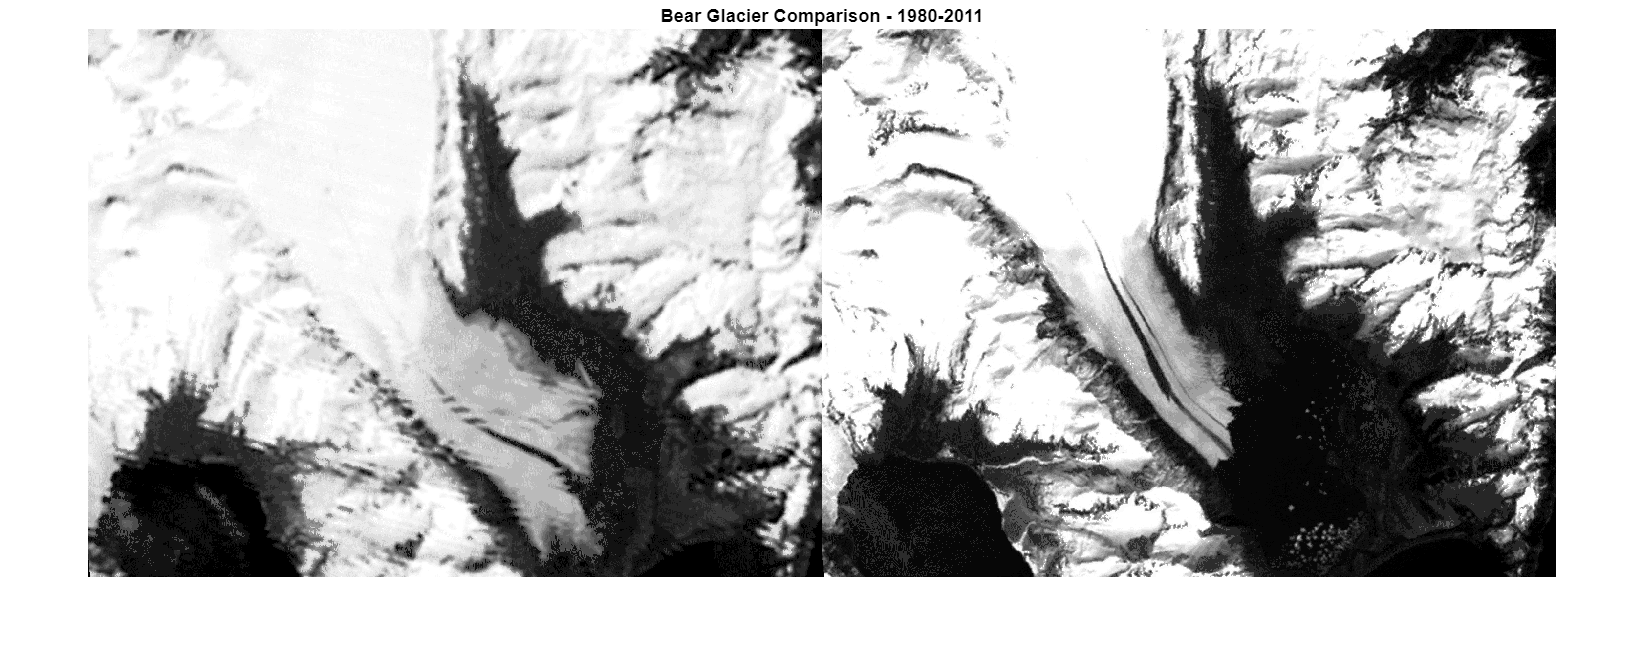

imshowpair(gs1980, gs2011, "montage")
title("Bear Glacier Comparison - 1980-2011")